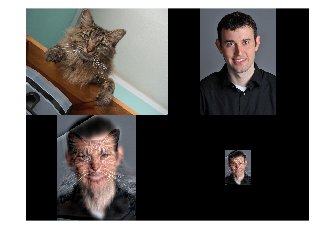

%572_merged
%{

YOUR COMMENTS:

Please include brief comments here describing the effects and quality of results (3-5 lines),
including how you arrived at good values of low and high frequency cutoffs.
Include anything else about the images you would like to share.

I tried to choose each pair of images with similar shapes to better align
the hybrid effect. I think by and large my hybrid images showed the effect
quite well - in particular, I think the flipflops / boots was a good choice
but could have done with a more busy background to hide the outline of the
boot image a bit better from afar but was helped out by both using legs as a basis.
The cow / moose hybrid also came out particularly well
for the same reason, that being because the shapes shared were so close. 
Personally, I did also liked my flower / telletubby hybrid.

For the low and high cutoff values, I would start each at approximately 15
or 20, and then from there determine if the afar image looked correct,
mostly like the base image. If it was too blurred out, I would reduce the
low point cutoff. And, if the "near" image with the high frequencies was too
apparent in looking at the hybrid from afar, then I would increase the high
cutoff. Then, similarly, I would look up close and determine if the "near"
image was distinct enough, and if not, I would lower the high cutoff until
I achieved satisfactory results.

%}

close('all');    % Close all figures so we start with a clean slate

% read images and convert to single format
set1_far = im2double(imread('https://lcms-files.mathworks.com/content/images/6c30a77d-d298-4f58-a114-f5bce78b049c.jpg')); 		        % "far" picture
set1_near = im2double(imread('https://lcms-files.mathworks.com/content/images/da802988-95a1-48b0-b641-7ca06105b87a.jpg')); 	    		% "near" picture
% (Optional) convert to grayscale
%set1_far = rgb2gray(set1_far)
%set1_near = rgb2gray(set1_near);


% Uncomment the call to get_points_interactively() to set the corresponding
% points in the two images to establish alignment (e.g., by the eyes).
% The function performs translation, rotation and scaling to align those 
% two points in the two images.
%[x1, y1, x2, y2] = get_points_interactively(set1_near, set1_far);
x1 = [605.1403 758.9682]; y1 = [287.3709 360.6136];
x2 = [303.8974 442.5175]; y2 = [348.1681 332.5175];
[set1_near_aligned, set1_far_aligned] = align_images(set1_near, set1_far, x1, y1, x2, y2);


%% Choose the cutoff frequencies for the low-pass and high-pass filters
cutoff_low  = 15.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!

%% Compute the hybrid image (you supply this code)

set1_hybrid = hybridImage(set1_far_aligned, set1_near_aligned, cutoff_low, cutoff_high);

%% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set2_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you these coordinates, uncomment the lines above, and 
% hard code the values below.
x = [90 680]; y = [370 1160];
set1_hybrid = set1_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set1_hybrid);
viewed_from_afar = padarray(set1_hybrid, max(h, w));
figure; montage({set1_near, set1_far, set1_hybrid, viewed_from_afar}, 'Size', [2,2]);

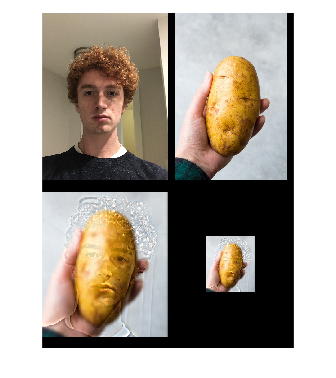



%%
% -------------------------------------------------------------------------
% IMPORTANT NOTE (please read carefully)
% -------------------------------------------------------------------------
% Repeat your method for 5 more sets of images.  But remember that for
% these you must interactively specify the mask and alignment ONE TIME.
%
% Work in the Matlab computer app or the full Matlab Online version
% (https://matlab.mathworks.com) first to get the coordinates for alignment
% and cropping.  Then hard-code these in your program before migrating to
% the Matlab Grader website for submission.
%
% -------------------------------------------------------------------------



set2_far = im2double(imread('https://i0.wp.com/kristineskitchenblog.com/wp-content/uploads/2019/01/Instant-Pot-Baked-Potatoes-700-4398.jpg?resize=600%2C900&ssl=1')); 		        % "far" picture
set2_near = im2double(imread('https://i.postimg.cc/25fpkBSJ/FA17-F7-AA-0-BCD-4-FBE-89-F7-94-C2-C17431-C9.jpg')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%[x1, y1, x2, y2] = get_points_interactively(set2_near, set2_far);
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [2.261141552511416e+02;3.344855403348555e+02]; y1 = [3.834528158295282e+02;3.858881278538813e+02];
x2 = [2.463904109589042e+02;3.778972602739727e+02]; y2 = [4.409109589041095e+02;4.600890410958904e+02];

[set2_near_aligned, set2_far_aligned] = align_images(set2_near, set2_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 20;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 15;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set2_hybrid = hybridImage(set2_far_aligned, set2_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set2_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [12;488]; y = [119;668];
set2_hybrid = set2_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set2_hybrid);
viewed_from_afar = padarray(set2_hybrid, max(h, w));
figure; montage({set2_near, set2_far, set2_hybrid, viewed_from_afar}, 'Size', [2,2]);

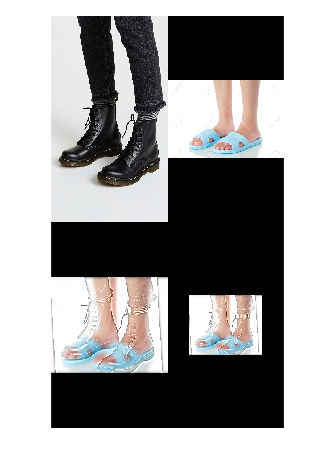






set3_far = im2double(imread('https://previews.123rf.com/images/kintarapong/kintarapong1707/kintarapong170700003/81702978-pieds-de-femme-portant-une-belle-sandale-bleue-debout-avec-une-vue-lat%C3%A9rale-sur-fond-blanc-concept-d.jpg')); 		        % "far" picture
set3_near = im2double(imread('https://i.pinimg.com/736x/e2/7e/6a/e27e6a120c1b2f93d2fbbc37d020d340.jpg')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%[x1, y1, x2, y2] = get_points_interactively(set3_near, set3_far);
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [49.870063694267630;6.151299363057324e+02]; y1 = [8.288980891719743e+02;8.588853503184712e+02];
x2 = [2.435070063694266e+02;1.055284076433121e+03]; y2 = [7.034878980891720e+02;6.990700636942676e+02];

[set3_near_aligned, set3_far_aligned] = align_images(set3_near, set3_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 15;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 18;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set3_hybrid = hybridImage(set3_far_aligned, set3_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set3_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [27;752]; y = [2;598];
set3_hybrid = set3_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set3_hybrid);
viewed_from_afar = padarray(set3_hybrid, max(h, w));
figure; montage({set3_near, set3_far, set3_hybrid, viewed_from_afar}, 'Size', [2,2]);

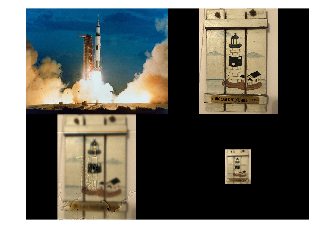






set4_far = im2double(imread('https://i.postimg.cc/pLyrcdR2/3-A8-A2500-1900-4-FA2-AAE8-01-DBD9-F103-BF.jpg')); 		        % "far" picture
set4_near = im2double(imread('https://images.immediate.co.uk/production/volatile/sites/25/2020/03/Saturn-V-launch-a3c5965.jpg?quality=45&resize=768,574')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%[x1, y1, x2, y2] = get_points_interactively(set4_near, set4_far);
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [3.942327188940093e+02;3.889239631336407e+02]; y1 = [48.605990783410220;3.423571428571428e+02];
x2 = [2.806749271137026e+02;2.783425655976676e+02]; y2 = [1.929198250728862e+02;5.660976676384838e+02];

[set4_near_aligned, set4_far_aligned] = align_images(set4_near, set4_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 20;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 22;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set4_hybrid = hybridImage(set4_far_aligned, set4_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set4_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [34;494]; y = [32;651];
set4_hybrid = set4_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set4_hybrid);
viewed_from_afar = padarray(set4_hybrid, max(h, w));
figure; montage({set4_near, set4_far, set4_hybrid, viewed_from_afar}, 'Size', [2,2]);

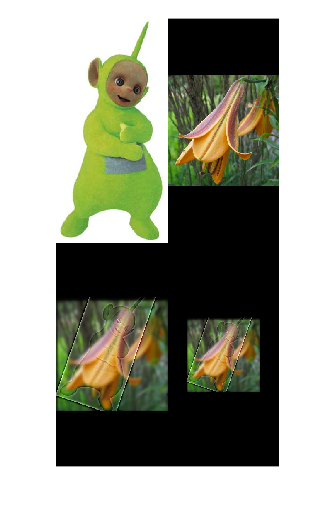





set5_far = im2double(imread('https://cdn.shopify.com/s/files/1/0034/6554/3793/products/african_queen_60e1e6f8-19c4-49e0-b46d-b0bcbcd8cf9c_520x.jpg?v=1606767825')); 		        % "far" picture
set5_near = im2double(imread('https://static.wikia.nocookie.net/tubbies/images/d/d9/Dipsy.jpg/revision/latest?cb=20120502063534')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
%[x1, y1, x2, y2] = get_points_interactively(set5_near, set5_far);
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [1.687827988338192e+02;1.281297376093294e+02]; y1 = [81.080174927113720;4.179198250728863e+02];
x2 = [3.416078717201166e+02;1.657478134110788e+02]; y2 = [39.158892128279945;4.030072886297377e+02];

[set5_near_aligned, set5_far_aligned] = align_images(set5_near, set5_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 15;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 20;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set5_hybrid = hybridImage(set5_far_aligned, set5_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set5_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [3;441]; y = [53;500];
set5_hybrid = set5_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set5_hybrid);
viewed_from_afar = padarray(set5_hybrid, max(h, w));
figure; montage({set5_near, set5_far, set5_hybrid, viewed_from_afar}, 'Size', [2,2]);

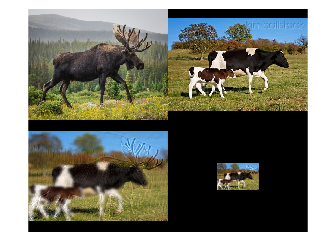





set5_far = im2double(imread('https://i.pinimg.com/564x/ca/af/cd/caafcdd65ea15867c767528270078004.jpg')); 		        % "far" picture
set5_near = im2double(imread('https://www.mercurynews.com/wp-content/uploads/2022/02/SJM-L-MONJOAN-0221-01_94320116.jpg?w=437')); 	    		% "near" picture
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
% [x1, y1, x2, y2] = get_points_interactively(set2_near, set2_far);
% Once you have these coordinates, comment out call to the interactive
% function above and hard code the coordinates instead.
x1 = [82.147230320699680;3.273629737609329e+02]; y1 = [1.526151603498543e+02;1.444752186588922e+02];
x2 = [1.496935483870967e+02;4.112142857142857e+02]; y2 = [1.248732718894009e+02;1.386981566820277e+02];

[set5_near_aligned, set5_far_aligned] = align_images(set5_near, set5_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 20;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 30;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)


% Compute the hybrid image (you supply this code)
set5_hybrid = hybridImage(set5_far_aligned, set5_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set2_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [54;449]; y = [79;333];
set5_hybrid = set5_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set5_hybrid);
viewed_from_afar = padarray(set5_hybrid, max(h, w));
figure; montage({set5_near, set5_far, set5_hybrid, viewed_from_afar}, 'Size', [2,2]);


%{

% REPEAT ABOVE FOR IMAGE SET 3
% REPEAT ABOVE FOR IMAGE SET 4
% REPEAT ABOVE FOR IMAGE SET 5
% REPEAT ABOVE FOR IMAGE SET 6

%}


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your function appears below 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function im12 = hybridImage(im1, im2, cutoff_low, cutoff_high)

    [im1_y, im1_x, rgb1] = size(im1);
    [im2_y, im2_x, rgb2] = size(im2);

    im1_fft = zeros([im1_y, im1_x, rgb1]);
    im2_fft = zeros([im2_y, im2_x, rgb2]);
    im12 = zeros([im2_y, im2_x, rgb2]);


    for i = 1:rgb1
        im = im1(:,:,i);
        im_fft = fftshift(fft2(im));
        gauss_lowpass = fspecial('gaussian', [im1_y, im1_x], cutoff_low);
        gauss_lowpass = gauss_lowpass/max(gauss_lowpass,[],'all');
        im_fft_lowpass = im_fft.*gauss_lowpass;
        im1_fft(:,:,i) = im_fft_lowpass;

        im = im2(:,:,i);
        im_fft = fftshift(fft2(im));
        gauss_highpass = fspecial('gaussian', [im2_y, im2_x], cutoff_high);
        gauss_highpass = gauss_highpass/max(gauss_highpass,[],'all');
        im_fft_highpass = im_fft.*(1-gauss_highpass);
        im2_fft(:,:,i) = im_fft_highpass;

        im12(:,:,i) = im2_fft(:,:,i) + im1_fft(:,:,i);
        im12(:,:,i) = real(ifft2(ifftshift(im12(:,:,i))));
    end

end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Helper functions. (You DO NOT need to change)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x1, y1, x2, y2] = get_points_interactively(im1, im2)
    % displays image and gets two points from the user
    fig=figure; hold off, imagesc(im1), axis image;
    disp('Select two points from each image define rotation, scale, translation')
    figure(fig)
    [x1, y1] = ginput(2);
    figure(fig); hold off, imagesc(im2), axis image;
    figure(fig)
    [x2, y2] = ginput(2);
    close(fig);
end

function [im1, im2] = align_images(im1, im2, x1, y1, x2, y2)
    % Aligns im1 and im2 (translation, scale, rotation) after getting two pairs
    % of points from the user.  In the output of im1 and im2, the two pairs of
    % points will have approximately the same coordinates.
    
    % get image sizes
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    cx1 = mean(x1); cy1 = mean(y1);
    cx2 = mean(x2); cy2 = mean(y2);
    
    % translate first so that center of ref points is center of image
    tx = round((w1/2-cx1)*2);
    if tx > 0,  im1 = padarray(im1, [0 tx], 'pre');
    else        im1 = padarray(im1, [0 -tx], 'post');
    end
    ty = round((h1/2-cy1)*2);
    if ty > 0,  im1 = padarray(im1, [ty 0], 'pre');
    else        im1 = padarray(im1, [-ty 0], 'post');
    end  
    tx = round((w2/2-cx2)*2) ;
    if tx > 0,  im2 = padarray(im2, [0 tx], 'pre');
    else        im2 = padarray(im2, [0 -tx], 'post');
    end
    ty = round((h2/2-cy2)*2);
    if ty > 0,  im2 = padarray(im2, [ty 0], 'pre');
    else        im2 = padarray(im2, [-ty 0], 'post');
    end
    
    % downscale larger image so that lengths between ref points are the same
    len1 = sqrt((y1(2)-y1(1)).^2+(x1(2)-x1(1)).^2);
    len2 = sqrt((y2(2)-y2(1)).^2+(x2(2)-x2(1)).^2);
    dscale = len2 ./ len1;
    if dscale < 1
        im1 = imresize(im1, dscale, 'bilinear'); 
    else
        im2 = imresize(im2, 1./dscale, 'bilinear');
    end
    
    % rotate im1 so that angle between points is the same
    theta1 = atan2(-(y1(2)-y1(1)), x1(2)-x1(1)); % in matlab, y==1 is at the top of the N x M image, and y==N is at the bottom
    theta2 = atan2(-(y2(2)-y2(1)), x2(2)-x2(1));
    dtheta = theta2-theta1;
    im1 = imrotate(im1, dtheta*180/pi, 'bilinear'); % imrotate uses degree units
    
    % Crop images (on both sides of border) to be same height and width
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    minw = min(w1, w2);
    brd = (max(w1, w2)-minw)/2;
    if minw == w1 % crop w2
        im2 = im2(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx-ceil(brd);
    else
        im1 = im1(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx+ceil(brd);    
    end
    
    minh = min(h1, h2);
    brd = (max(h1, h2)-minh)/2;
    if minh == h1 % crop w2
        im2 = im2((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty-ceil(brd);
    else
        im1 = im1((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty+ceil(brd);    
    end    
end
